How big should an claw area be to carry the force transfered

R = 0.1; %m afstand fra axel til claw
T_max = 10000;
% T = F*R
F= T_max/R

F =       100000



Sy = 370; %MPa
% S = F/A
A = F/Sy % mm^2

A =            270.27027027027



A/4 % Area pr teeth for 4 teeth claw coupling

ans =           67.5675675675676



10*10

ans =    100



F = 10*10 * Sy

F =        37000


Internal strain on the coupling due to rotaiton

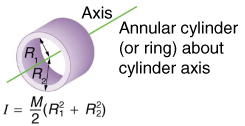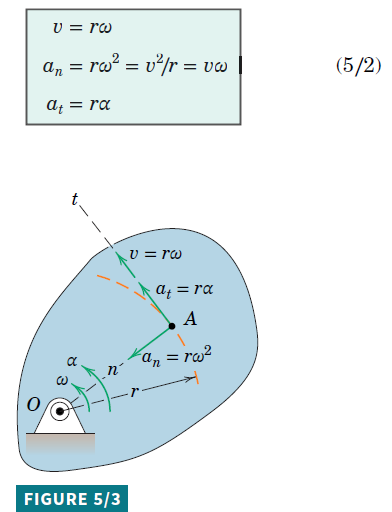

clear all
clf
format longg

g = 9.82;
R2 = 0.2; %m % outer radius 
R1 = 0.1; %m % inner radius 
L = 0.3;
rho = 7850;%kg/m^3
m = rho * pi*(R2^2 - R1^2)

m =           739.845069920396


M = m * L % kg % mass of the slinger part(shoe)

M =           221.953520976119



n = 7200; % rpm % at 120 Hz 
I = M/2 * (R1^2 + R2^2 )

I =           5.54883802440297


E = 200e9; %Youngs modulus
omega = 2 * pi / 60 * n; % rad/s % vinkel hastigheden
a_n = (R2+R1)/2 * omega^2 % Normal acceleration (radialt)

a_n =           85273.3820254121


F_n = a_n * M

F_n =           18926727.3860819



A = (R2+R1)/2 * L

A =                      0.045


S_max = F_n / A /1e6

S_max =           420.593941912931


S_y = 370

S_y =    370



F_n < S_y

ans = logical
   0


centrifugal stress


S_c = rho * R2^2 * omega^2 /1e6

S_c =           178.505613039863



N_c = 30 * g / (pi*L^2) * sqrt(E*I/m)

N_c =           40353944.2712262
